# №1

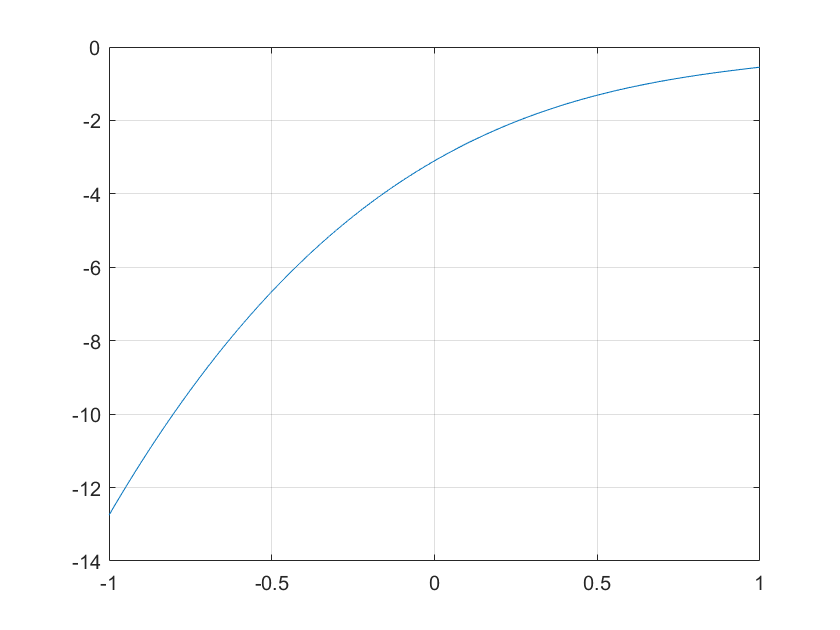

p = [1, -3.55, 5.1, -3.1];
x = linspace(-1,1,100);
f = polyval(p,x);
plot(x,f); 
grid on;

disp(roots(p));

   1.5500 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i



## №2 a)

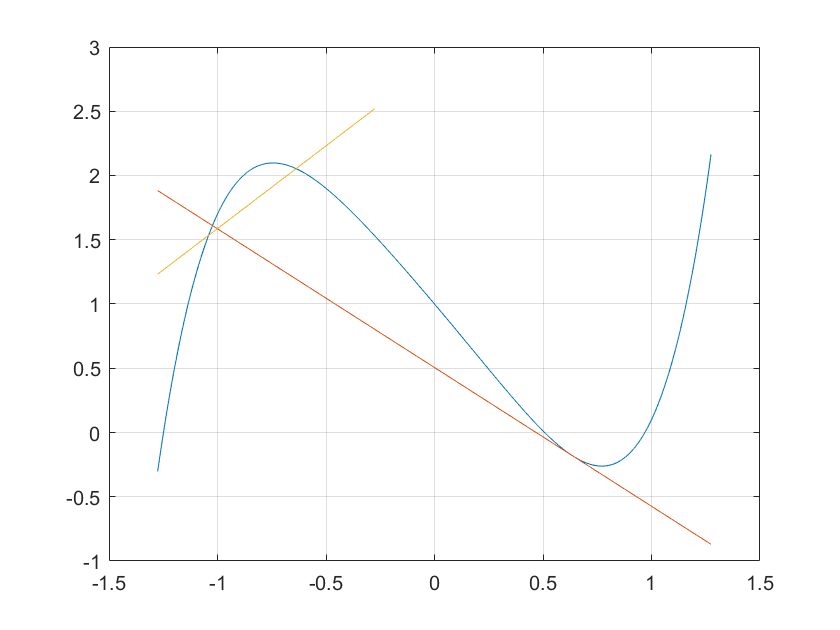

p = [1, 0.1, 0.2, -0.2, -2, 1];
rt = roots(p);
rt_max = max(rt);
x = -abs(rt_max):0.01:abs(rt_max);
y = polyval(p,x);
dp = polyder(p);
plot(x,y);
grid on; hold on;
x1 = 1/2*abs(rt_max);
y_tang = polyval(p,x1)+polyval(dp,x1).*(x-x1);
plot(x,y_tang);
hold on;
x2 = -1/2*abs(rt_max);
x2_k = 1/(polyval(dp,x2));
x = -abs(rt_max):0.01:-abs(rt_max)+1;
y_perp = -x2_k.*x+x2_k*x2+polyval(p,x2);
plot(x,y_perp);
hold off;

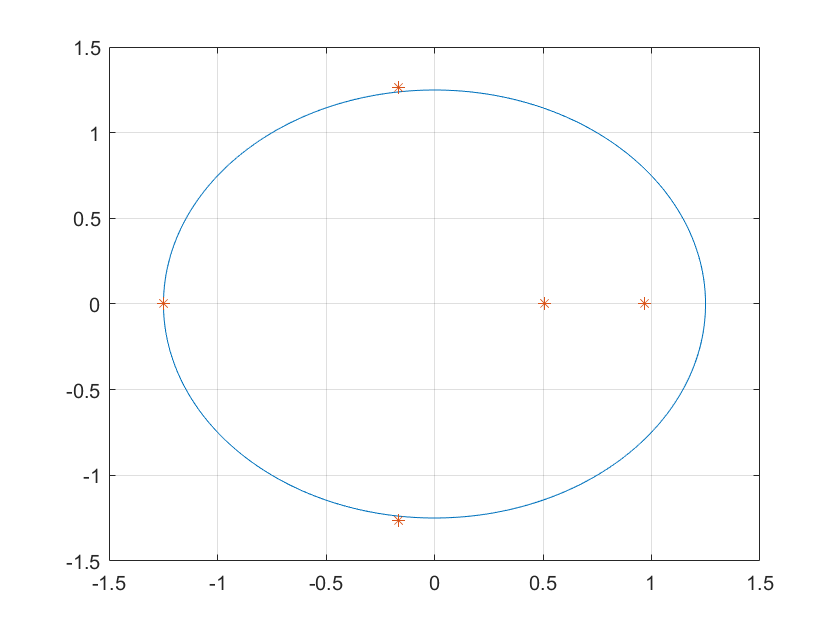

t = 0:0.01:2*pi;
real_rt = real(rt(1));
u = real_rt*cos(t);
v = real_rt*sin(t);
plot(u,v);
hold on
plot(real(rt),imag(rt),'*');
grid on;
hold off;

## 4

p = [1 -2  6 -10 16];
c = 4;
p_horner = [1 -c];
[q1,r1] = deconv(p,p_horner);
[q2,r2] = deconv(q1,p_horner);
disp(r2(4));

   198



disp(polyval(polyder(p),c));

   198



p = [1 (1+2*1i) 0 -(1+3*1i) 0 7];
c = -2-1i;
p_horner = [1 -c];
[q1,r1] = deconv(p,p_horner);
[q2,r2] = deconv(q1,p_horner);
disp(r2(5));

  43.0000 +74.0000i



disp(polyval(polyder(p),c));

  43.0000 +74.0000i



## №5

p = [];
n = 4;
i = 2*n;
while (i>=0)
    switch i
        case 2*n
            p = [p 1];
        case n+1
            p = [p -n];
        case n-1
            p = [p n];
        case 0
            p = [p -1];
        otherwise
            p = [p 0];
    end
    i = i-1;
end
rt = sign(real(roots(p)).*(abs(roots(p))));
for i=1:length(rt)
    kr(i)=length(find(rt==rt(i)));
end
for i=1:length(rt)
    if (kr(i)>1)
        res(i)=rt(i);
    end
end
disp(unique(res));

    -1     1



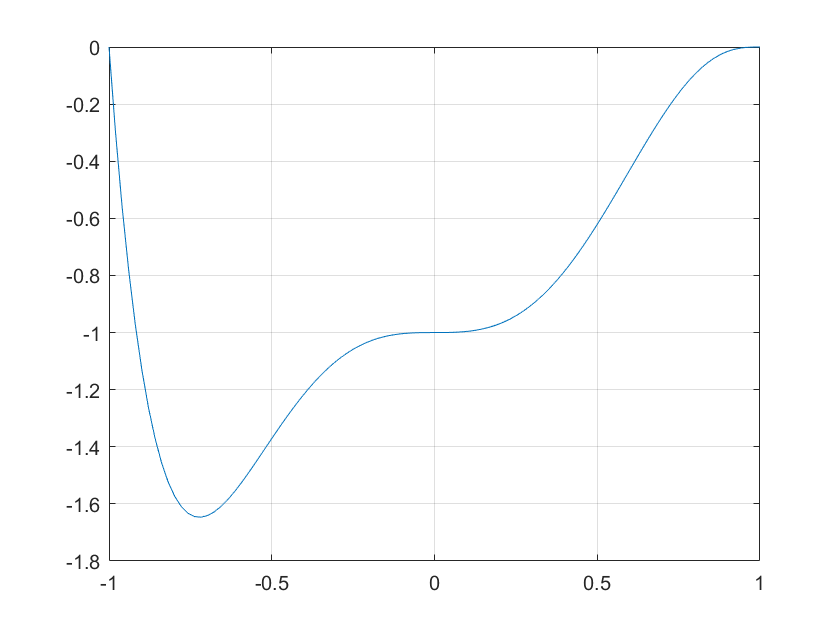

x = linspace(-1,1,100);
f = polyval(p,x);
plot(x,f);
grid on;

## №6 1)

a = [1 0 0];
b = [1 4 1 -6];
[r,p,k] = residue(a,b);
for i=1:length(r)
    if (p(i)<0)
        fprintf("%.3f/x%.3f",r(i),p(i))
    else
        fprintf("%.3f/x+%.3f",r(i),p(i))
    end
    if ((i~=length(r)) && (r(i+1)>=0))
        fprintf("+ ")
    elseif ((r(i))<0)
        fprintf ("- ")
        elseif (k ~= [])
        fprintf("%.3f  ", k);
    else
        fprintf("  ");
    end
end 

2.250/(x-3.000)

-1.333/(x-2.000)

+ 

0.083/(x+1.000)

## №6 2)

a = [1 3];
b = [1 1 -1 -1];
[r,p,k] = residue(a,b);
for i=1:length(r)
    if (p(i)<0)
        fprintf("%.3f/x%.3f",r(i),p(i))
    else
        fprintf("%.3f/x+%.3f",r(i),p(i))
    end
    if (i~=length(r))
        fprintf("+ ");
        elseif (k ~= [])
        fprintf("%.3f  ", k);
    else
        fprintf("  ");
    end
end 

-1.000/(x-1.000)

+ 

-1.000/(x-1.000)

+ 

1.000/(x+1.000)

## №6 3)

a = [1 0 0];
b = [1 0 0 0 -1];
[r,p,k] = residue(a,b);
for i=1:length(r)
    if ((p(i)<0) && (r(i)~=0))
        fprintf("%.3f/x%.3f",r(i),p(i))
    elseif (r(i)~=0)
        fprintf("%.3f/x+%.3f",r(i),p(i))
    end
    if (i~=length(r))
        fprintf("+ ");
        elseif (k ~= [])
        fprintf("%.3f  ", k);
    else
        fprintf("  ");
    end
end

-0.250/x-1.000

+ 

0.250/x+1.000

+ 

0.000/x+0.000

+ 

0.000/x+0.000

## №7 1)

n = 10;
x = 1:n;
y = ones(1,n)./x;
p = polyfit(x,y,3/5*n);
rt = roots(p);
xx = min(rt):0.01:max(rt);

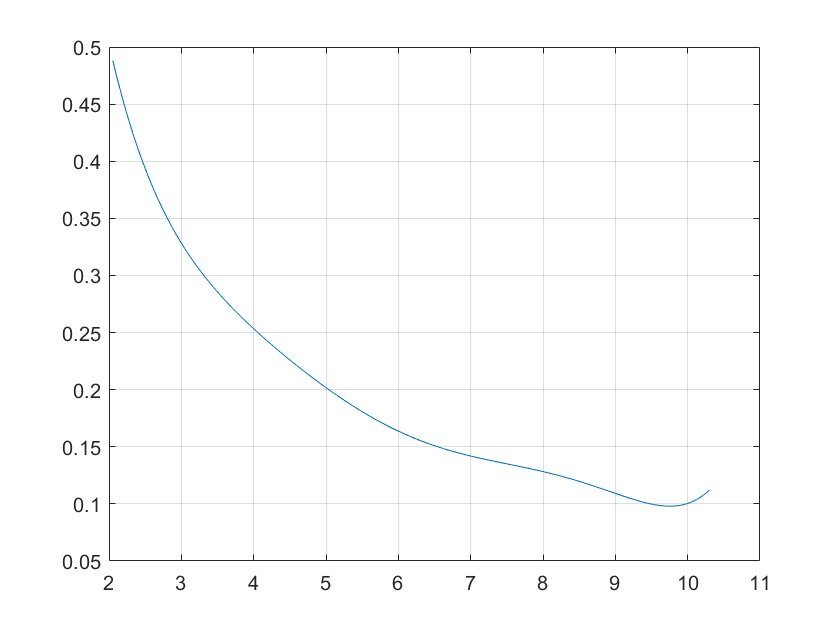

yy = polyval(p,xx);
plot(xx,yy);
grid on;

## №7 2)

x = [-1 0 1 2 3]';
y = [6 5 0 3 2]';
p = polyfit(x,y,3/5*n);

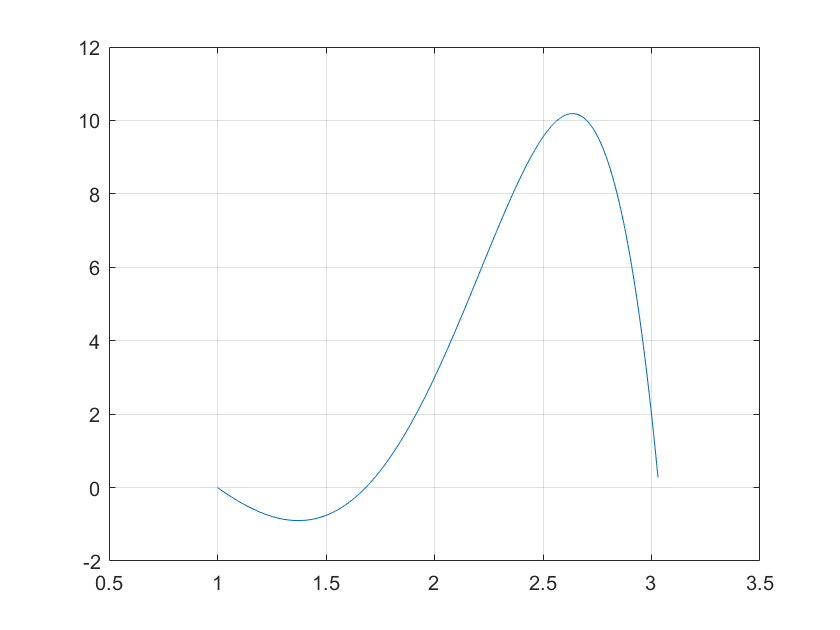

rt = roots(p);
xx = min(rt):0.01:max(rt);
yy = polyval(p,xx);
plot(xx,yy);
grid on;